clear
clc

## Transfer function setup

s = tf('s');

% Defining variables for transfer function
N = 1/3;        % Gearing
k = 0.01;       % Motor konstant
J_tilt = 1.576*10^-2;     % Tilt system inertia
J_pan = 6.342*10^-2;      % Pan system inertia
R_tilt = 14;    % Tilt system resistance
R_pan = 8;      % Pan system resistance
b = 1*10^-4;    % Viscous friction

% System transfer function
Gs_tilt = ( k*N ) / ( s * (J_tilt*R_tilt*s + (k*N)^2 + b*N/R_tilt) );
Gs_pan  = ( k*N ) / ( s * (J_pan*R_pan*s + (k*N)^2 + b*N/R_pan) );

% Extracting num and den from tf's
[Num_tilt, Den_tilt] = tfdata(Gs_tilt, 'v');
[Num_pan, Den_pan] = tfdata(Gs_pan, 'v');


## TILT SYSTEM ANALYSIS

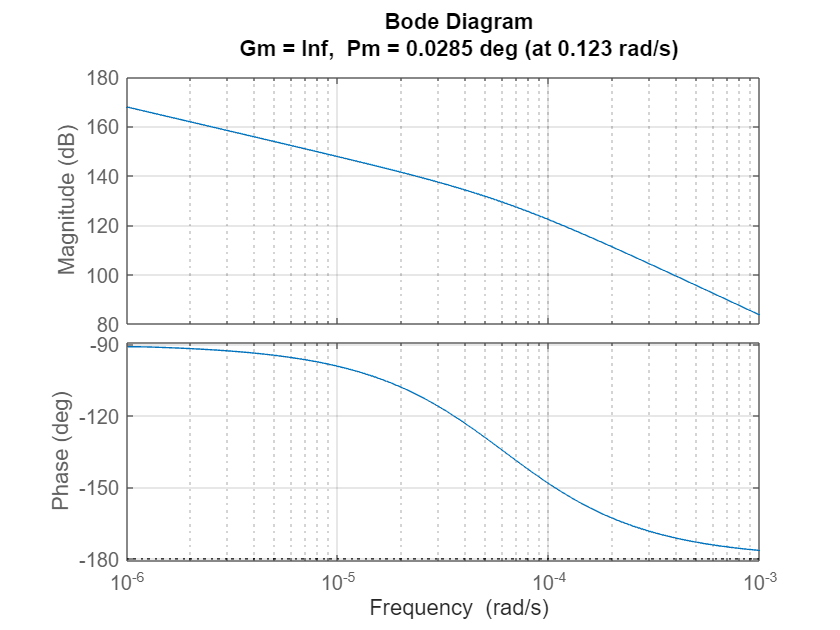

margin(Gs_tilt), grid

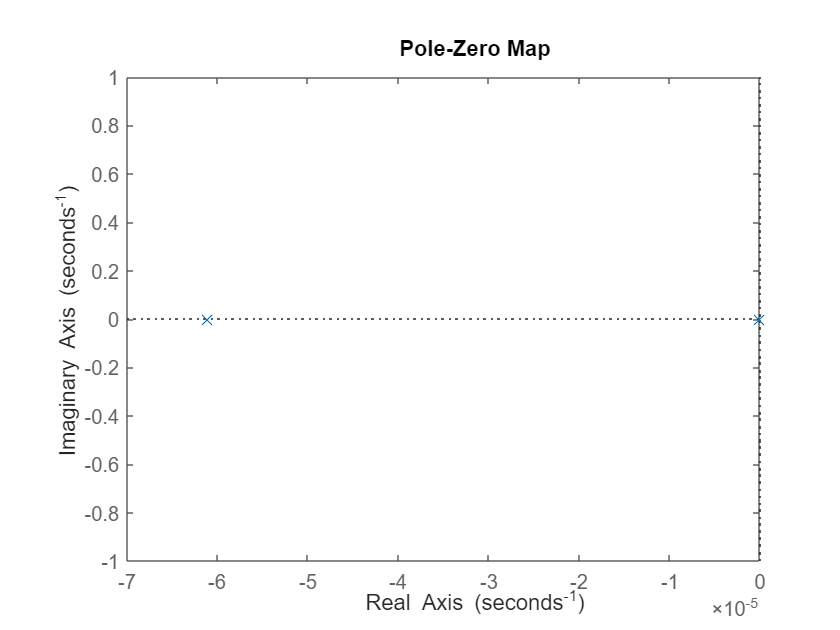

pzmap(Gs_tilt)

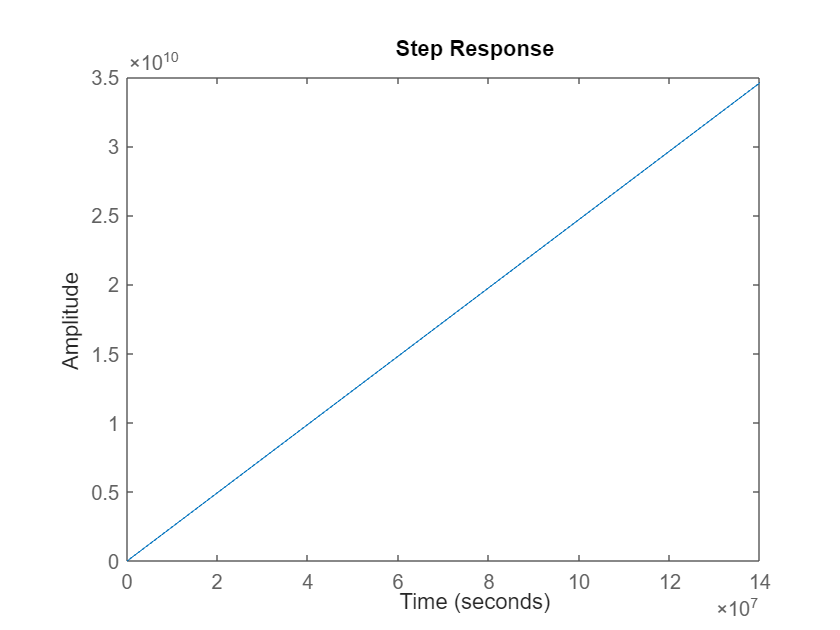

step(Gs_tilt)

## PID controlled tilt system (Continous time)

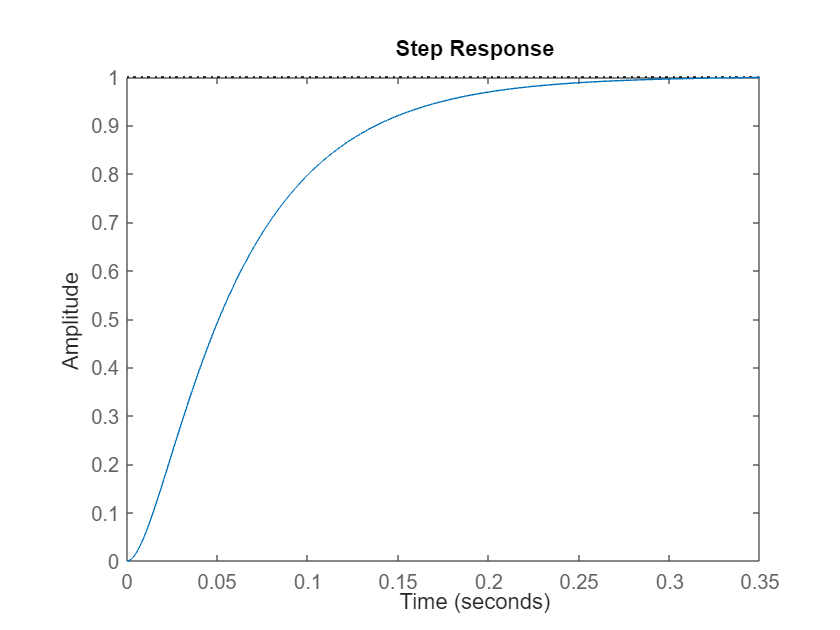

Kp_tilt = 10;
Ki_tilt = 0.5;
Kd_tilt = 100;
N_tilt = 10000;   % Derivative filter divisor

C_tilt = pidstd(Kp_tilt, Ki_tilt, Kd_tilt, N_tilt);
Tcl_tilt = feedback(C_tilt * Gs_tilt, 1);

step(Tcl_tilt)

stepinfo(Tcl_tilt)

ans = struct with fields:
         RiseTime: 0.1234
    TransientTime: 0.2229
     SettlingTime: 0.2229
      SettlingMin: 0.9003
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 0.3607


## PID controlled pan system (Continous time)

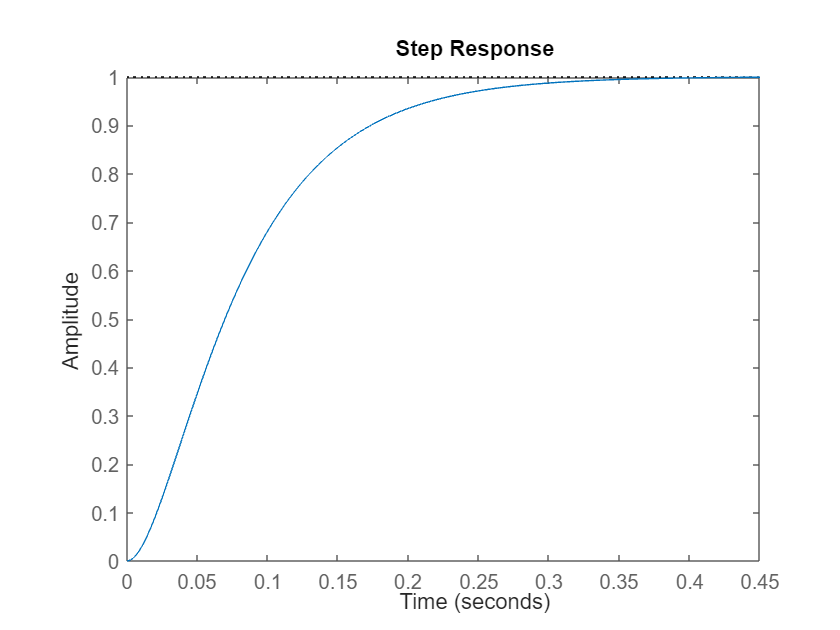

Kp_pan = 10;
Ki_pan = 0.5;
Kd_pan = 176;
N_pan = 10000;   % Derivative filter divisor

C_pan = pidstd(Kp_pan, Ki_pan, Kd_pan, N_pan);
Tcl_pan = feedback(C_pan * Gs_pan, 1);

step(Tcl_pan)

stepinfo(Tcl_pan)

ans = struct with fields:
         RiseTime: 0.1521
    TransientTime: 0.2716
     SettlingTime: 0.2716
      SettlingMin: 0.9019
      SettlingMax: 1.0005
        Overshoot: 0.0480
       Undershoot: 0
             Peak: 1.0005
         PeakTime: 0.5187


## PID controlled tilt system (Discrete time)

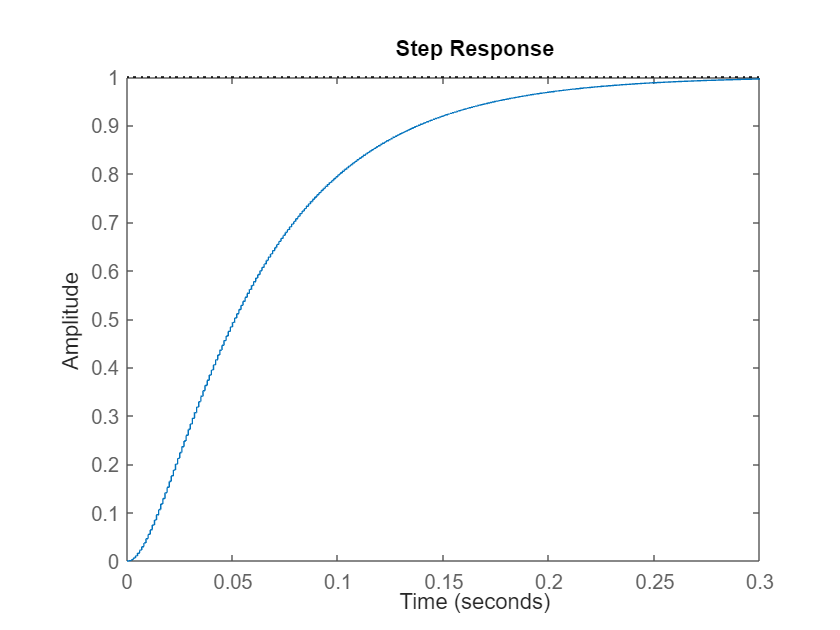

Ts_tilt = 0.001;
dTcl_tilt = c2d(Tcl_tilt, Ts_tilt);
step(dTcl_tilt)

stepinfo(dTcl_tilt)

ans = struct with fields:
         RiseTime: 0.1230
    TransientTime: 0.2230
     SettlingTime: 0.2230
      SettlingMin: 0.9004
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 0.3490


## PID controlled pan system (Discrete time)

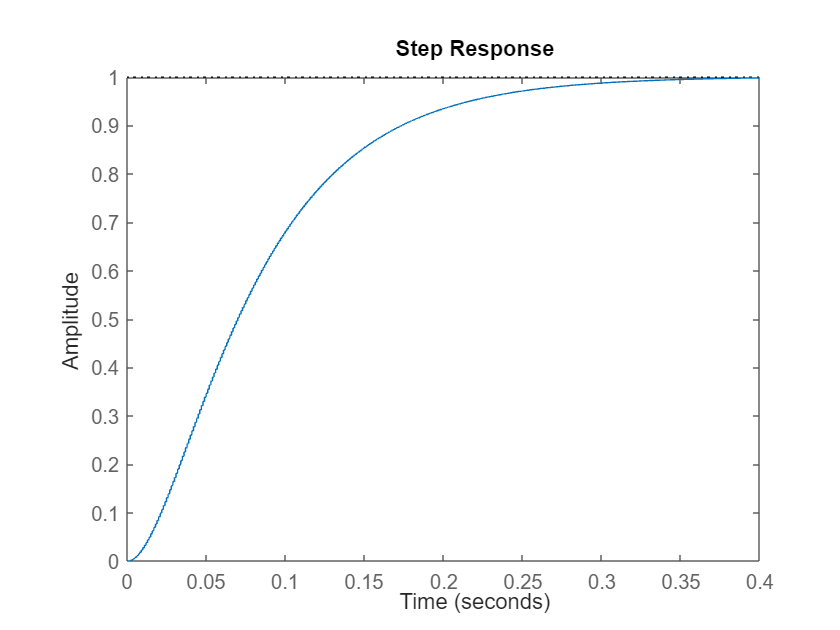

Ts_pan = 0.001;
dTcl_pan = c2d(Tcl_pan, Ts_pan);
step(dTcl_pan)

stepinfo(dTcl_pan)

ans = struct with fields:
         RiseTime: 0.1520
    TransientTime: 0.2720
     SettlingTime: 0.2720
      SettlingMin: 0.9012
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 0.4390
